# Algoritmos geneticos (codificación binaria)

Un algoritmo genético típicamente tiene:

- Una población de posibles soluciones.

- Una manera de calcular que tan buenas o malas son las soluciones (selección).

- Un método para mezclar fragmentos de las mejores soluciones (cruza).

- Un operador de mutación (mutación).

Esas operaciones se pueden realizar en distintos tipos de codificación: binaria o decimal.

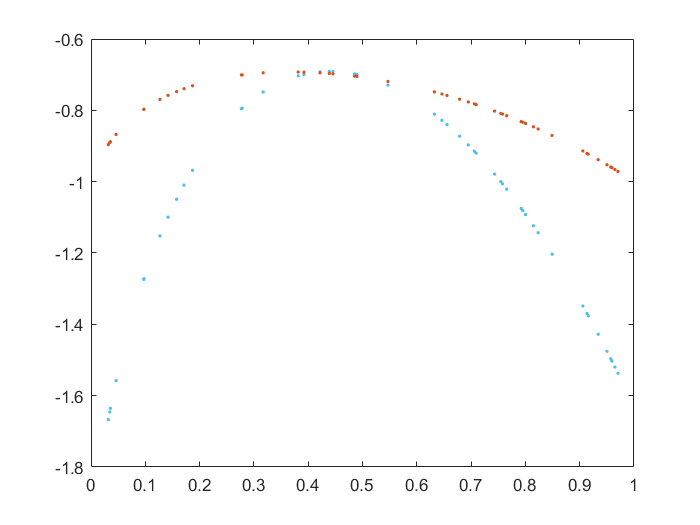

Unable to perform assignment because the size of the left side is 50-by-1 and the size of the right side is 50-by-50.

Error in GenericAlgorithm_CodificacionBinaria>seleccionbinaria (line 122)
    Matriz(:,D+1) = (Prob_y);

clear; clf

% Cantidad de iteraciones
N = 50;
ciclos = 150;
mutacion = 0.7;
razonmutacion = 0.975;

% Parametros de precision
D = 18;  % Se ajusta al usar la funcion de2bi
exponente = 4;

% Prealocar  % IndividuosBinarios = zeros(N, D+1);
y_max = zeros(ciclos,1);

% Generacion de la poblacion inicial
rng('default');
pd = makedist('Uniform',0,1);
x = random(pd,N,1);

% Funcion
funcion = 2;
switch funcion
    case 1
        f1 = @(x) (x.^2 + x).*cos(x);
        xs = -10:0.1:10;
        
    case 2
        f1 = @(x) (sin((x.^x)./(x+1)) + x.^2 - sqrt(x))/(x.*cos((x+1)./x.^2))-x.^x;
        xs = 0:0.01:1;
        
end


for nn=1:ciclos
    
    % Evaluacion de la funcion (fitness)
    y = f1(x);
    
    % PLOTS
    plot(xs, f1(xs),"--", x, y, '.');
    pause(0.1)
    
    % X en binario
    x_bin = de2bi(floor(abs(x) .* (10^exponente)),D);
    xsign = 0 .* (sign(x)>=0) + 1 .* (sign(x)<0);
    
    % Ordena de mejor a peor
    IndividuosBinarios = seleccionbinaria([xsign x_bin], exp(y));
    
    for ii=1:N
        % Seleccion
        p = randsample(N,2,true,IndividuosBinarios(:,D+2));
        padre1 = IndividuosBinarios(p(1),1:D+1);
        padre2 = IndividuosBinarios(p(2),1:D+1);
      
        % Cruza
        [hijo1, hijo2] = cruzabinaria(padre1, padre2);
        
        % Solo sobrevive un hijo :c
        psurv = round(rand());
        hijo = hijo1 .* (psurv==0) + hijo2 .* (psurv==1);
        
        % Mutacion
        hijomutado = mutacionbinaria(hijo,mutacion);
        
        % De regreso a decimal
        x(ii) = ((-1)^(hijomutado(1))) * bi2de(hijomutado(2:D+1)) ./ (10^exponente);
        
        % Condicion para quedarse dentro del dominio de busqueda
%         if abs(x(ii))>10
%             delx = abs(10 - abs(x(ii)));
%             x(ii) = sign(x(ii))*10 - sign(x(ii))*delx;
%         end

        if x(ii)>1
            delx = abs(1 - x(ii));
            x(ii) = x(ii) - delx ;
        elseif x(ii)<0
            delx = abs(1 - x(ii));
            x(ii) = x(ii) + delx  ;    
        end

    end
    
    % Cambio en la mutacion
    mutacion = razonmutacion * mutacion;

    y_max(nn) = max(y);
end

xmax = x(end), max_val= y_max(end), mean_max_x = mean(x), mean_max_fun = mean(y_max)

plot(y_max)


## Funciones

function mutado = mutacionbinaria(individuo, mutacion)
    % Mutación de la cadena binaria
    D = length(individuo);
    mutado = individuo;
    cantidad = floor(mod(mutacion*D,D));
    posicion_mutada = randperm(D, cantidad);
%     posicion_mutada = posicion_mutada(1,:)
    mutado(posicion_mutada) = 1 .* (individuo(posicion_mutada)==0) + ...
                              0 .* (individuo(posicion_mutada)==1);
end

function [hijo1, hijo2] = cruzabinaria(padre1, padre2)
    n = length(padre1);
    corte = randi([2, n-1]);
    hijo1 = [padre1(1:corte) padre2(corte+1:end)];
    hijo2 = [padre2(1:corte) padre1(corte+1:end)];
end

function M = seleccionbinaria(xbin,y)
    D = size(xbin,2);

    % Probabilidades
    Prob_y = y./(sum(y) + 1 .* (sum(y)==0)) + (1/size(xbin,1)) .* (sum(y)==0);
    
    % Llenamos la matriz IndividuosBinarios
    Matriz = zeros(size(xbin,1), size(xbin,2)+1);
    Matriz(:,1:D) = xbin;
    Matriz(:,D+1) = (Prob_y);
    
    % Acomoda la matriz y realiza una suma acumulada para sus probabilidades
    % respectivas
    M = sortrows(Matriz,D+1);
    M(:,D+1) = cumsum(M(:,D+1));
end